# Find Weights

High Baseline Model

lb = 10^-5;
ub = 60;
ub_neg = -30;
%s_x = randstart(12,lb,ub)
%s_w = randstart(2,ub_neg,ub)
%s_w2 = [-47.9581 -29.3471];
%s_x2 = [33.5761 56.7630 58.6119 0.1153 59.9942 56.4312 4.3897 7.6217 50.1281 16.2599 0.9777 54.8493]
d = load("ga_solution2.mat");
s_x3 = d.solution.x;
s_w3 = d.solution.W23;
%s_x3([3,12]) = [14 14];
%s_w3 = -[.1 .4];


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

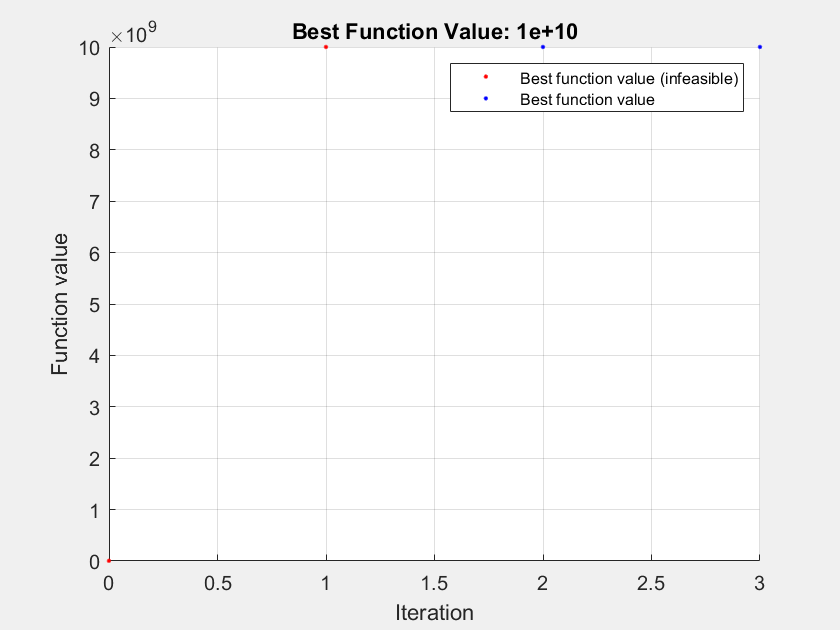


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the  value of the constraint tolerance.

<stopping criteria details>


solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


reasonSolverStopped2 =     OptimalSolution


objectiveValue2 = 1.0000e+10

% Create optimization variables
x2 = optimvar("x",1,12,"LowerBound",lb,"UpperBound",ub);
W232 = optimvar("W23",1,2,"LowerBound",ub_neg,"UpperBound",ub);

% Set initial starting point for the solver
initialPoint.x = s_x3;
initialPoint.W23 = s_w3;

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@Error,x2,W232);

% Define problem constraints
problem.Constraints = nlcon2(x2,W232);

% Set nondefault solver options
options2 = optimoptions("ga","Display","iter","MutationFcn",...
    "mutationadaptfeasible","UseParallel",true,"PlotFcn",["gaplotscores",...
    "gaplotbestf"]);

% Display problem information
show(problem);

% Clear variables
clearvars x2 W232 initialPoint options2


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


> In Model6/compute (line 184)
In Model6 (line 135)
In LiveEditorEvaluationHelperE469592868>Error (

solution2 = struct with fields:
    W23: [-7.9225 -0.9028]
      x: [1.0000e-05 1.0558 60 35.7226 9.2299 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 1.0000e-05 5.3125]


objectiveValue2 = 1.0000e+10


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       Error(x, W23)


	subject to :
       arg_LHS >= arg_RHS

       where:

             arg1 = zeros(1, 6);
             arg8 = ((272.5801 .* W23(1)) .* x(3));
             arg12 = (((272.5801 .* W23(1)) .* x(4)) .* x(5));
             arg15 = ((272.5801 .* x(4)) .* x(6));
             arg18 = (25 .* (35 - (33.02 .* ((-1) + (x(4) .* x(6))))));
             arg19 = ((((((1728.2801 - ((247.65 .* W23(1)) .* x(3))) - ((247.65 .* W23(1)) .* x(3))) - arg8) - arg12) - arg15) + arg18);
             arg1(1) = ((19446.3035 + (25 .* (1455.7 + (272.5801 .* (1 - (x(4) .* x(6))))))) + (8 .* arg19));
             arg28 = ((16.51 .* W23(1)) .* x(3));
             arg32 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg36 = (((16.51 .* W23(1)) .* x(4)) .* x(5));
             arg39 = ((25 .* x(4)) .*

Solving problem using fmincon.


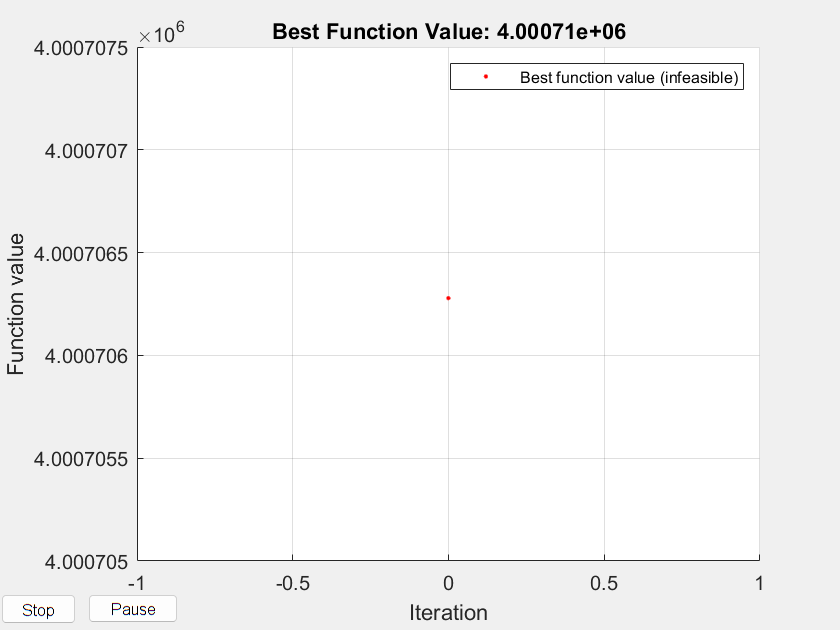


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     15  4.00071e+06    9.991e+04                                         Infeasible start point


objectiveValue2 = 10^6;
while objectiveValue2 >= 10^6
    %s_x = randstart(12,lb,ub)
    %s_w = randstart(2,ub_neg,ub)
    d = load("ga_solution2.mat");
    s_x = max(d.solution.x + 5*randn(1,12),10^-5);
    s_w = d.solution.W23;

    % Create optimization variables
    x4 = optimvar("x",1,12,"LowerBound",lb,"UpperBound",ub);
    W234 = optimvar("W23",1,2,"LowerBound",ub_neg,"UpperBound",ub);

    % Set initial starting point for the solver
    initialPoint3.x = s_x3;
    initialPoint3.W23 = s_w3;

    % Create problem
    problem = optimproblem;

    % Define problem objective
    problem.Objective = fcn2optimexpr(@Error,x4,W234);

    % Define problem constraints
    problem.Constraints = nlcon2(x4,W234);

    % Set nondefault solver options
    options3 = optimoptions("fmincon","Algorithm","active-set","Display","iter",...
        "UseParallel",true,"PlotFcn","optimplotfvalconstr");

    % Display problem information
    show(problem);

    % Solve problem
    [solution2,objectiveValue2,reasonSolverStopped2] = solve(problem,initialPoint3,...
        "Solver","fmincon","Options",options3);

    % Display results
    solution2
    %reasonSolverStopped2
    objectiveValue2

    % Clear variables
    clearvars x4 W234 initialPoint3 options3 reasonSolverStopped2
end

T = [8 25 20 15 16.51 16.51];
    Ba = [55 18.5 7.25 7.25 25 25]./1000; 
    M = [200 300 200 200 500 500]./1000;
e = Error(solution.x,solution.W23)

e = 4.0007e+06

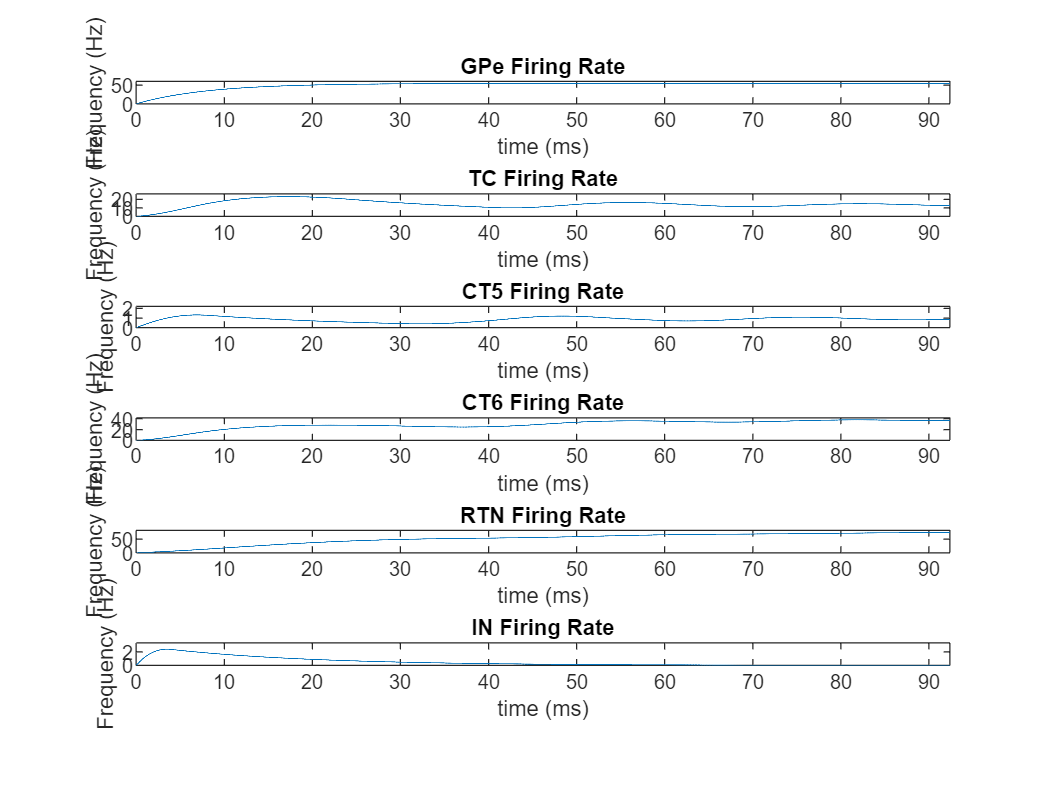

w = zeros(6);
    w(1,2) = solution.x(1);    
    w(1,6) = solution.x(2);
    w(3,2) = solution.x(3);
    w(3,4) = solution.x(4);
    w(4,2) = solution.x(5);
    w(4,3) = solution.x(6);
    w(4,5) = solution.x(7);
    w(4,6) = solution.x(8);
    w(5,2) = solution.x(9);
    w(5,6) = solution.x(10);
    w(6,2) = solution.x(11);
    w(2,3) = solution.W23(1);
 v = zeros(6);
    v(1,2) = solution.x(1);
    v(1,6) = solution.x(2);
    v(3,2) = solution.x(12);  % w32PD
    v(3,4) = solution.x(4);
    v(4,2) = solution.x(5);
    v(4,3) = solution.x(6);
    v(4,5) = solution.x(7);
    v(4,6) = solution.x(8);
    v(5,2) = solution.x(9);
    v(5,6) = solution.x(10);
    v(6,2) = solution.x(11);
    v(2,3) = solution.W23(2);  % w23PD
[t1,y1,period0,SS] = Model6(zeros(6,1),w,T,Ba,M);

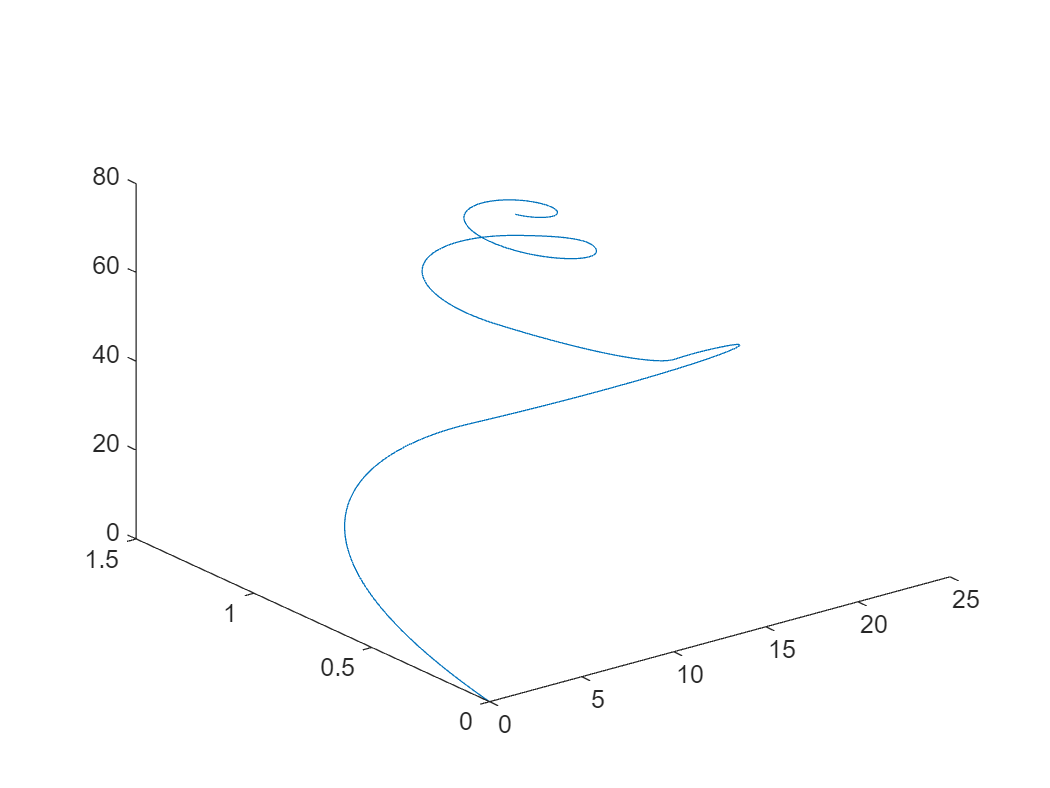

%nlcon(solution.x,solution.W23)
%nlcon2(solution.x,solution.W23)
figure;
plot3(1000*y1(2,:),1000*y1(3,:),1000*y1(5,:))

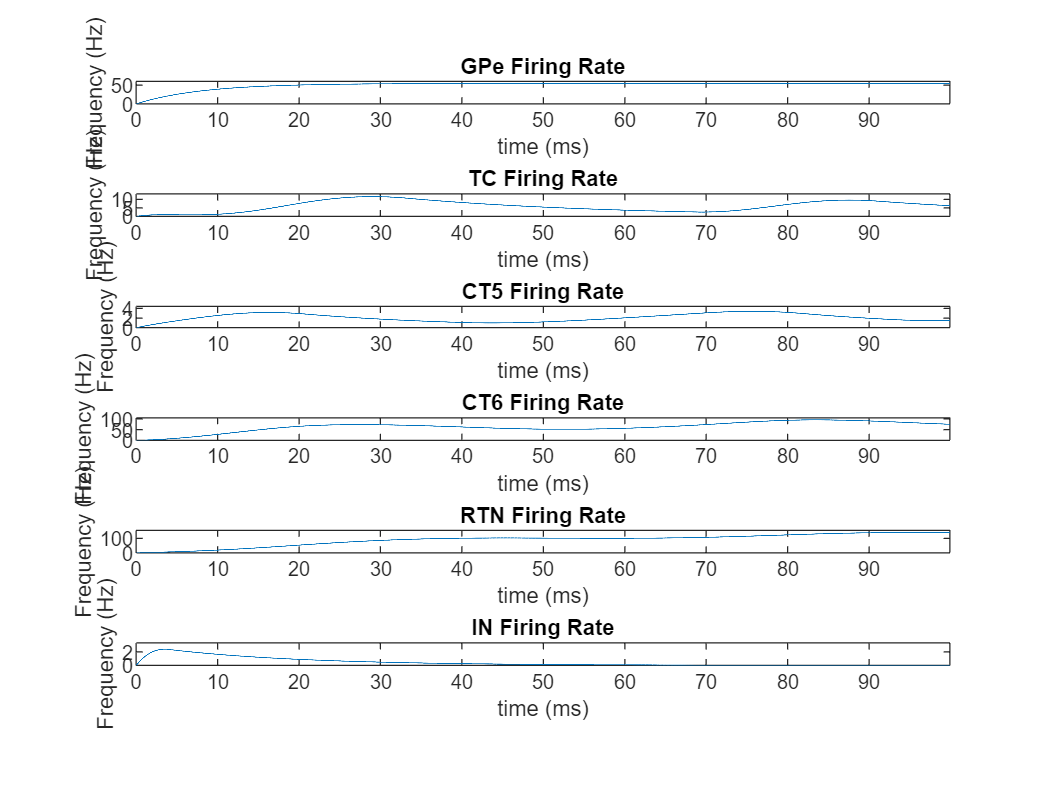

[t2,y2,period] = Model6(zeros(6,1),v,T,Ba,M);

1000/period

ans = Inf

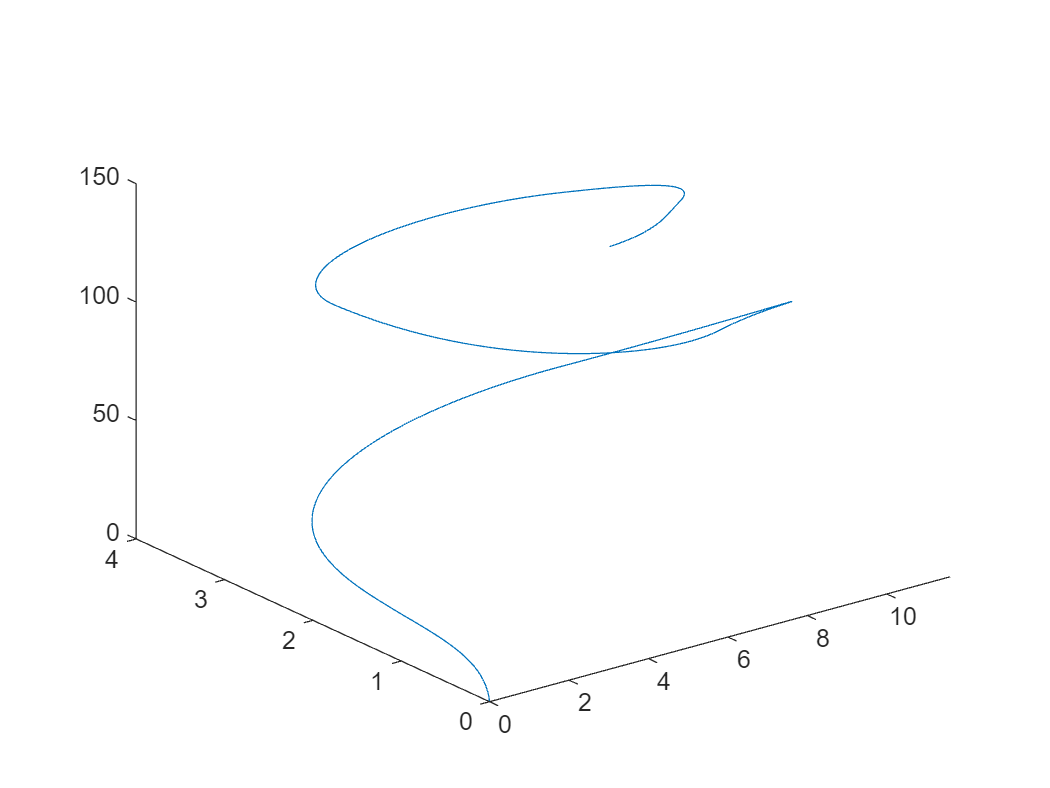

figure;
plot3(1000*y2(2,:),1000*y2(3,:),1000*y2(5,:))

## Supporting Functions

function w = randstart(n,lb,ub)
    w = rand([1,n]) * (ub-lb) + lb;
end

### Error Function

function e = Error(x,W23) 
    b = 22.7;
    y_Hthy_data = [73.5 15.15 19.133 16.008 40 40]'; 
    y_Hthy_SD = [18.1 2.9334 19.078 21.387 2 2]';
    y_PD_data = [78.1 8.6364 13.554 8.37 40 40]';
    y_PD_SD = [17.9 1.44 14.57 7.972 2 2]';

    T = [8 25 20 15 16.51 16.51];
    Ba = [55 18.5 7.25 7.25 25 25]./1000; 
    M = [200 300 200 200 500 500]./1000;
    
    e1=0;
    e2=0;
    e3=0;
    e4=0;
    ep=0;
    ef=0;

    %%%%% Err 1: matching Hthy data %%%%%
    w = zeros(6);
    w(1,2) = x(1);
    w(1,6) = x(2);
    w(3,2) = x(3);
    w(3,4) = x(4);
    w(4,2) = x(5);
    w(4,3) = x(6);
    w(4,5) = x(7);
    w(4,6) = x(8);
    w(5,2) = x(9);
    w(5,6) = x(10);
    w(6,2) = x(11);
    w(2,3) = W23(1);
    [~,y1,~,SS,flag] = Model6(zeros(6,1),w,T,Ba,M,'graphless');
    if ~flag
        y1_last = y1(:,end).*1000;
        e1 = sum(((y1_last(2:end) - y_Hthy_data(2:end))./y_Hthy_SD(2:end)).^2);

        if ~and(all(SS{2,2,2,2,2,2}<M),all(SS{2,2,2,2,2,2}>0))
            e3 = 10^6;
        end
    else
        ef = 10^10;
    end

    %%%%% Err 2: matching PD data %%%%%
    v = zeros(6);
    v(1,2) = x(1);
    v(1,6) = x(2);
    v(3,2) = x(12);  % w32PD
    v(3,4) = x(4);
    v(4,2) = x(5);
    v(4,3) = x(6);
    v(4,5) = x(7);
    v(4,6) = x(8);
    v(5,2) = x(9);
    v(5,6) = x(10);
    v(6,2) = x(11);
    v(2,3) = W23(2);  % w23PD
    [t2,y2,period,SS,flag]=Model6(zeros(6,1),v,T,Ba,M,'graphless');
    if ~flag
        if period ~=0
            in = find(t2-t2(end)+period>0,1);

            y2_avg = mean(y2(:,in:end),2)*1000;
            e2 = sum(((y2_avg(2:end) - y_PD_data(2:end))./y_PD_SD(2:end)).^2);
        else
            e2 = 10^6;
        end

        % at least
        if period == 0
            ep = 10^6;
        elseif 1000/period < 13
            ep = (1000/period-13)^2;
        elseif 1000/period > 30
            ep = (1000/period-30)^2;
        end

        if ~and(all(SS{2,2,2,2,2,2}<M),all(SS{2,2,2,2,2,2}>0))
            e4 = 10^6;
        end
    else
        ef = 10^10;
    end

    %%%%% Combine %%%%% 
    e = e1 + e2 + e3 + e4 + ep + ef;
end

#### Det & RH stable Only

function c = nlcon(x,W23) 

    T = [8 25 20 15 16.51];

    %%%%% Healthy %%%%%
    % det<0
c(1)= 10^-5 + (-1+W23(1)*x(3)+W23(1)*x(4)*x(5)+x(4)*x(6) ...
       -W23(1)*x(4)*x(7)*x(9)-W23(1)*x(4)*x(8)*x(11) ...
       +W23(1)*x(4)*x(7)*x(10)*x(11))<=0;  

c(2)= 10^-5 + (T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2) ...
    *(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1) ...
    -T(5)*x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11) ...
    *W23(1))))/(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5)))) - (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)* ...
    T(4)*T(5)*(1-x(3)*W23(1))) <=0;

c(3)= 10^-5 - (((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)* ...
    T(4)*T(5)*(1-x(3)*W23(1)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+ ...
    T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5) ...
    *x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1)))- ...
    T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+ ...
    T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+T(4)+T(5)- ...
    T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)*x(3)*W23(1)- ...
    T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1)))^2+T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)* ...
    T(5)+T(3)*(T(4)+T(5))))*(1-x(3)*W23(1)-x(4)*(x(6)+(x(5)-x(7)* ...
    x(9)-x(8)*x(11)+x(7)*x(10)*x(11))*W23(1)))-(T(1)*T(3)*T(4)*T(5) ...
    +T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3) ...
    +T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)* ...
    x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1)- ...
    T(1)*(-1+x(3)*W23(1)+x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+ ...
    x(7)*x(10)*x(11))*W23(1)))))/((T(1)*T(3)*T(4)*T(5)+T(2)* ...
    T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+ ...
    T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3)*W23(1)))-T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)* ...
    x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)* ...
    x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)*x(3)*W23(1)- ...
    T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1))))) <=0;

c(4) = 10^-5 - (((1-x(3)*W23(1)-x(4)*(x(6)+(x(5)-x(7)*x(9)- ...
    x(8)*x(11)+x(7)*x(10)*x(11))*W23(1)))*((T(1)*T(3)*T(4)* ...
    T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))* ...
    (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+ ...
    T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)* ...
    (1-x(3)*W23(1)))^2-T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)* ...
    T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3)*W23(1)))*(T(3)* ...
    T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))- ...
    T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)- ...
    T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)*-T(5)*x(3)*W23(1)-T(5)*x(4) ...
    *x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1)))+T(1)^2*T(2)^2*T(3)^2* ...
    T(4)^2*T(5)^2*(1-x(3)*W23(1)-x(4)*(x(6)+(x(5)-x(7)*x(9)- ...
    x(8)*x(11)+x(7)*x(10)*x(11))*W23(1))))+(T(1)*T(3)*T(4)*T(5)+ ...
    T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1) ...
    -T(5)*x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11) ...
    *W23(1)-T(1)*(-1+x(3)*W23(1)+x(4)*(x(6)+(x(5)-x(7)*x(9) ...
    -x(8)*x(11)+x(7)*x(10)*x(11))*W23(1))))^2+(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)*x(3) ...
    *W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1) ...
    -T(1)*(-1+x(3)*W23(1)+x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8) ...
    *x(11)+x(7)*x(10)*x(11))*W23(1))))*(-((T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4) ...
    *T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+ ...
    T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1- ...
    x(3)*W23(1)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5) ...
    -T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+T(4)+ ...
    T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5) ...
    *x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11) ...
    *W23(1))))+T(1)*T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5) ...
    +T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1) ...
    +T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6) ...
    -T(4)*x(3)*W23(1)-T(5)*x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1) ...
    +T(5)*x(4)*x(8)*x(11)*W23(1)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-x(3) ...
    *W23(1)-x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+x(7) ...
    *x(10)*x(11))*W23(1))))))/(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)*+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5) ...
    +T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1) ...
    *T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3) ...
    *W23(1)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5) ...
    *x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)*x(3) ...
    *W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1)))) ...
    +T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3) ...
    +T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2) ...
    +T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3) ...
    *W23(1)-T(5)*x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4) ...
    *x(8)*x(11)*W23(1)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5) ...
    +T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5) ...
    *(-1+x(3)*W23(1)+x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11) ...
    +x(7)*x(10)*x(11))*W23(1)))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)*x(3) ...
    *W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1) ...
    -T(1)*(-1+x(3)*W23(1)+x(4)*(x(6)+(x(5)-x(7)*x(9) ...
    -x(8)*x(11)+x(7)*x(10)*x(11))*W23(1))))))) <=0; 

    %%%%% PD %%%%%

    % det<0
c(5)= 10^-5 + (-1+W23(2)*x(12)+W23(2)*x(4)*x(5)+x(4)*x(6) ...
       -W23(2)*x(4)*x(7)*x(9)-W23(2)*x(4)*x(8)*x(11) ...
       +W23(2)*x(4)*x(7)*x(10)*x(11)) <=0;  
end

function c = nlcon2(x,W23) 

    T = [8 25 20 15 16.51 16.51];

    %%%%% Healthy %%%%%
    % det<0
a = optimexpr(6,1);
d = optimexpr(1,1);
a(6)= 0*x(1) + T(1)*T(2)*T(3)*T(4)*T(5)*T(6);
a(5)= 0*x(1) + T(1)* T(3)* T(4)* T(5)* T(6)+ T(2)* T(3)* T(4)* T(5)* T(6)+  T(1)* T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6)));
a(4)= T(3)* T(4)* T(5)* T(6)+ T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6)))+  T(1)*( T(3)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))+ T(4)* T(5)* T(6)*(1-W23(1)*x(3))+  T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+ T(5)* T(6)*(1-x(4)*x(6))));
a(3)= T(3)* T(4)* T(5)+ T(3)* T(4)* T(6)+ T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)- T(4)* T(5)* T(6)*W23(1)*x(3)+  T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+ T(5)* T(6)*(1-x(4)*x(6)))+  T(1)*( T(4)* T(5)+ T(4)* T(6)+ T(5)* T(6)+ T(3)*( T(4)+ T(5)+ T(6))- T(4)* T(5)*W23(1)*x(3)-  T(4)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(4)*x(5)-  T(5)* T(6)*x(4)*x(6)+ T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6))));
a(2)= T(3)* T(4)+ T(3)* T(5)+ T(4)* T(5)+ T(3)* T(6)+ T(4)* T(6)+ T(5)* T(6)- T(4)* T(5)*W23(1)*x(3)-  T(4)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(4)*x(5)- T(5)* T(6)*x(4)*x(6)+  T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6)))+  T(1)*( T(2)+ T(3)+ T(4)+ T(5)+ T(6)- T(4)*W23(1)*x(3)- T(5)*W23(1)*x(3)-  T(6)*W23(1)*x(3)- T(5)*W23(1)*x(4)*x(5)- T(6)*W23(1)*x(4)*x(5)- T(2)*x(4)*x(6)-  T(5)*x(4)*x(6)- T(6)*x(4)*x(6)+ T(6)*W23(1)*x(4)*x(7)*x(9)+ T(5)*W23(1)*x(4)*x(8)*x(11));
a(1)= T(2)+ T(3)+ T(4)+ T(5)+ T(6)- T(4)*W23(1)*x(3)- T(5)*W23(1)*x(3)- T(6)*W23(1)*x(3)-  T(5)*W23(1)*x(4)*x(5)- T(6)*W23(1)*x(4)*x(5)- T(2)*x(4)*x(6)- T(5)*x(4)*x(6)-  T(6)*x(4)*x(6)+ T(6)*W23(1)*x(4)*x(7)*x(9)+ T(5)*W23(1)*x(4)*x(8)*x(11)-  T(1)*(-1+x(4)*x(6)+ W23(1)*(x(3)+x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))));
d=1-x(4)*x(6)-W23(1)*(x(3)+x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))); 

c(1)= T(3)* T(4)* T(5)+ T(3)* T(4)* T(6)+ T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+  T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+ T(5)* T(6)*(1-x(4)*x(6)))+  T(1)*( T(4)* T(5)+ T(4)* T(6)+ T(5)* T(6)+ T(3)*( T(4)+ T(5)+ T(6))- T(4)* T(5)*W23(1)*x(3)-  T(4)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(4)*x(5)-  T(5)* T(6)*x(4)*x(6)+ T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6))))>= 10^-5 +  T(4)* T(5)* T(6)*W23(1)* x(3)+(( T(1)* T(3)* T(4)* T(5)* T(6)+ T(2)* T(3)* T(4)* T(5)* T(6)+  T(1)* T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))))*( T(3)* T(4)+  T(3)* T(5)+ T(4)* T(5)+ T(3)* T(6)+ T(4)* T(6)+ T(5)* T(6)- T(4)* T(5)*W23(1)*x(3)-  T(4)* T(6)*W23(1)*x(3)-  T(5)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(4)*x(5)- T(5)* T(6)*x(4)*x(6)+  T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6)))+  T(1)*( T(2)+ T(3)+ T(4)+ T(5)+ T(6)- T(4)*W23(1)*x(3)- T(5)*W23(1)*x(3)-  T(6)*W23(1)*x(3)- T(5)*W23(1)*x(4)*x(5)-  T(6)*W23(1)*x(4)*x(5)- T(2)*x(4)*x(6)- T(5)*x(4)*x(6)-  T(6)*x(4)*x(6)+ T(6)*W23(1)*x(4)*x(7)*x(9)+ T(5)*W23(1)*x(4)*x(8)*x(11))))/( T(3)*  T(4)* T(5)* T(6)+ T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6)))+   T(1)*( T(3)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))+ T(4)* T(5)* T(6)*(1-W23(1)*x(3))+  T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+ T(5)* T(6)*(1-x(4)*x(6))))) ;
c(2)=(( T(1)* T(3)* T(4)* T(5)* T(6)+ T(2)* T(3)* T(4)* T(5)* T(6)+  T(1)* T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))))* (-(( T(1)* T(3)* T(4)* T(5)* T(6)+ T(2)* T(3)* T(4)* T(5)* T(6)+  T(1)* T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))))*( T(3)* T(4)+  T(3)* T(5)+ T(4)* T(5)+ T(3)* T(6)+ T(4)* T(6)+ T(5)* T(6)- T(4)* T(5)*W23(1)*x(3)-  T(4)* T(6)*W23(1)*x(3)-  T(5)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(4)*x(5)-  T(5)* T(6)*x(4)*x(6)+ T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6)))+  T(1)*( T(2)+ T(3)+ T(4)+ T(5)+ T(6)- T(4)*W23(1)*x(3)- T(5)*W23(1)*x(3)-  T(6)*W23(1)*x(3)-  T(5)*W23(1)*x(4)*x(5)- T(6)*W23(1)*x(4)*x(5)-  T(2)*x(4)*x(6)- T(5)*x(4)*x(6)- T(6)*x(4)*x(6)+  T(6)*W23(1)*x(4)*x(7)*x(9)+ T(5)*W23(1)*x(4)*x(8)*x(11))))+ ( T(3)* T(4)* T(5)* T(6)+  T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6)))+  T(1)*( T(3)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))+ T(4)* T(5)* T(6)*(1-W23(1)*x(3))+   T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))))*(1+ T(3)* T(4)* T(5)+ T(3)* T(4)* T(6)+  T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)- T(4)* T(5)* T(6)*W23(1)*x(3)-x(4)*x(6)+   T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))+  T(1)*( T(4)* T(5)+ T(4)* T(6)+ T(5)* T(6)+ T(3)*( T(4)+ T(5)+ T(6))-  T(4)* T(5)*W23(1)*x(3)- T(4)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(3)-  T(5)* T(6)*W23(1)*x(4)*x(5)- T(5)* T(6)*x(4)*x(6)+  T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6))))- W23(1)*(x(3)+ x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11)))))- ( T(3)* T(4)* T(5)* T(6)+ T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6)))+  T(1)*( T(3)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))+ T(4)* T(5)* T(6)*(1-W23(1)*x(3))+  T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))))^  2*( T(2)+ T(3)+ T(4)+ T(5)+ T(6)- T(4)*W23(1)*x(3)- T(5)*W23(1)*x(3)-  T(6)*W23(1)*x(3)- T(5)*W23(1)*x(4)*x(5)- T(6)*W23(1)*x(4)*x(5)- T(2)*x(4)*x(6)-  T(5)*x(4)*x(6)- T(6)*x(4)*x(6)+ T(6)*W23(1)*x(4)*x(7)*x(9)+  T(5)*W23(1)*x(4)*x(8)*x(11)-  T(1)*(-1+x(4)*x(6)+ W23(1)*(x(3)+x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))))))/ (( T(3)* T(4)* T(5)* T(6)+ T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6)))+  T(1)*( T(3)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))+ T(4)* T(5)* T(6)*(1-W23(1)*x(3))+  T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))))* ( T(3)* T(4)* T(5)+ T(3)* T(4)* T(6)+ T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)-  T(4)* T(5)* T(6)*W23(1)*x(3)+  T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+ T(5)* T(6)*(1-x(4)*x(6)))+   T(1)*( T(4)* T(5)+ T(4)* T(6)+ T(5)* T(6)+ T(3)*( T(4)+ T(5)+ T(6))-  T(4)* T(5)*W23(1)*x(3)- T(4)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(3)-  T(5)* T(6)*W23(1)*x(4)*x(5)- T(5)* T(6)*x(4)*x(6)+  T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6)))))- ( T(1)* T(3)* T(4)* T(5)* T(6)+ T(2)* T(3)* T(4)* T(5)* T(6)+  T(1)* T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))))*( T(3)* T(4)+  T(3)* T(5)+ T(4)* T(5)+ T(3)* T(6)+ T(4)* T(6)+ T(5)* T(6)- T(4)* T(5)*W23(1)*x(3)-  T(4)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(3)-  T(5)* T(6)*W23(1)*x(4)*x(5)- T(5)* T(6)*x(4)*x(6)+  T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6)))+  T(1)*( T(2)+ T(3)+ T(4)+ T(5)+ T(6)- T(4)*W23(1)*x(3)- T(5)*W23(1)*x(3)-  T(6)*W23(1)*x(3)- T(5)*W23(1)*x(4)*x(5)-  T(6)*W23(1)*x(4)*x(5)- T(2)*x(4)*x(6)- T(5)*x(4)*x(6)-  T(6)*x(4)*x(6)+ T(6)*W23(1)*x(4)*x(7)*x(9)+ T(5)*W23(1)*x(4)*x(8)*x(11))))>=10^-5;
c(3)= T(2)+ T(3)+ T(4)+ T(5)+ T(6)+ T(6)*W23(1)*x(4)*x(7)*x(9)+  T(5)*W23(1)*x(4)*x(8)* x(11)+(((- T(3))* T(4)- T(3)* T(5)- T(4)* T(5)- T(3)* T(6)- T(4)* T(6)- T(5)* T(6)+  T(4)* T(5)*W23(1)*x(3)+ T(4)* T(6)*W23(1)*x(3)+ T(5)* T(6)*W23(1)*x(3)+  T(5)* T(6)*W23(1)*x(4)*x(5)+ T(5)* T(6)*x(4)*x(6)+  T(2)*(- T(4)+ T(3)*(-1+ T(4)* T(5)* T(6))+( T(5)+ T(6))*(-1+x(4)*x(6)))+  T(1)*(- T(3)- T(4)- T(5)- T(6)+ T(3)* T(4)* T(5)* T(6)+ T(4)*W23(1)*x(3)+  T(5)*W23(1)*x(3)+ T(6)*W23(1)*x(3)+  T(5)*W23(1)*x(4)*x(5)+ T(6)*W23(1)*x(4)*x(5)+ T(5)*x(4)*x(6)+  T(6)*x(4)*x(6)+  T(2)*(-1+ T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))+x(4)*x(6))-  T(6)*W23(1)*x(4)*x(7)*x(9)- T(5)*W23(1)*x(4)*x(8)*x(11)))* (-1+x(4)*x(6)+ W23(1)*(x(3)+x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11)))))/( T(3)*  T(4)* T(5)* T(6)+ T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6)))+   T(1)*( T(3)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))+ T(4)* T(5)* T(6)*(1-W23(1)*x(3))+  T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))))+ ((1-x(4)*x(6)- W23(1)*(x(3)+x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))))* (-(( T(3)* T(4)* T(5)* T(6)+  T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6)))+  T(1)*( T(3)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))+  T(4)* T(5)* T(6)*(1-W23(1)*x(3))+   T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))))*( T(3)* T(4)* T(5)+ T(3)* T(4)* T(6)+  T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)- T(4)* T(5)* T(6)*W23(1)*x(3)+   T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))+  T(1)*( T(4)* T(5)+ T(4)* T(6)+ T(5)* T(6)+ T(3)*( T(4)+ T(5)+ T(6))-  T(4)* T(5)*W23(1)*x(3)- T(4)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(3)-  T(5)* T(6)*W23(1)*x(4)*x(5)- T(5)* T(6)*x(4)*x(6)+  T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6)))))^2)+( T(1)* T(3)*  T(4)* T(5)* T(6)+ T(2)* T(3)* T(4)* T(5)* T(6)+  T(1)* T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))))* ( T(3)* T(4)+ T(3)* T(5)+ T(4)* T(5)+ T(3)* T(6)+ T(4)* T(6)+ T(5)* T(6)-  T(4)* T(5)*W23(1)*x(3)- T(4)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(3)-  T(5)* T(6)*W23(1)*x(4)*x(5)- T(5)* T(6)*x(4)*x(6)+  T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6)))+   T(1)*( T(2)+ T(3)+ T(4)+ T(5)+ T(6)- T(4)*W23(1)*x(3)- T(5)*W23(1)*x(3)-  T(6)*W23(1)*x(3)- T(5)*W23(1)*x(4)*x(5)- T(6)*W23(1)*x(4)*x(5)-  T(2)*x(4)*x(6)- T(5)*x(4)*x(6)- T(6)*x(4)*x(6)+  T(6)*W23(1)*x(4)*x(7)*x(9)+  T(5)*W23(1)*x(4)*x(8)*x(11)))*(-1+ T(3)* T(4)* T(5)+  T(3)* T(4)* T(6)+ T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)- T(4)* T(5)* T(6)*W23(1)*x(3)+ x(4)*x(6)+  T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))+   T(1)*( T(4)* T(5)+ T(4)* T(6)+ T(5)* T(6)+ T(3)*( T(4)+ T(5)+ T(6))-  T(4)* T(5)*W23(1)*x(3)- T(4)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(3)-  T(5)* T(6)*W23(1)*x(4)*x(5)- T(5)* T(6)*x(4)*x(6)+  T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6))))+  W23(1)*(x(3)+ x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))))+( T(3)* T(4)*  T(5)* T(6)+ T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6)))+   T(1)*( T(3)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))+ T(4)* T(5)* T(6)*(1-W23(1)*x(3))+  T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))))* ( T(3)* T(4)+ T(3)* T(5)+ T(4)* T(5)+ T(3)* T(6)+ T(4)* T(6)+ T(5)* T(6)-  T(4)* T(5)*W23(1)*x(3)- T(4)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(3)-  T(5)* T(6)*W23(1)*x(4)*x(5)- T(5)* T(6)*x(4)*x(6)+  T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6)))+   T(1)*( T(2)+ T(3)+ T(4)+ T(5)+ T(6)- T(4)*W23(1)*x(3)- T(5)*W23(1)*x(3)-  T(6)*W23(1)*x(3)- T(5)*W23(1)*x(4)*x(5)- T(6)*W23(1)*x(4)*x(5)-  T(2)*x(4)*x(6)- T(5)*x(4)*x(6)- T(6)*x(4)*x(6)+  T(6)*W23(1)*x(4)*x(7)*x(9)+  T(5)*W23(1)*x(4)*x(8)*x(11)))*( T(2)+ T(3)+ T(4)+ T(5)+ T(6)-  T(4)*W23(1)*x(3)- T(5)*W23(1)*x(3)- T(6)*W23(1)*x(3)- T(5)*W23(1)*x(4)*x(5)-  T(6)*W23(1)*x(4)*x(5)- T(2)*x(4)*x(6)- T(5)*x(4)*x(6)- T(6)*x(4)*x(6)+  T(6)*W23(1)*x(4)*x(7)*x(9)+ T(5)*W23(1)*x(4)*x(8)*x(11)-  T(1)*(-1+x(4)*x(6)+ W23(1)*(x(3)+ x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11)))))))/ (( T(1)* T(3)* T(4)* T(5)* T(6)+ T(2)* T(3)* T(4)* T(5)* T(6)+  T(1)* T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))))* (-(( T(1)* T(3)* T(4)* T(5)* T(6)+ T(2)* T(3)* T(4)* T(5)* T(6)+  T(1)* T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))))*( T(3)* T(4)+  T(3)* T(5)+ T(4)* T(5)+ T(3)* T(6)+ T(4)* T(6)+ T(5)* T(6)- T(4)* T(5)*W23(1)*x(3)-  T(4)* T(6)*W23(1)*x(3)-  T(5)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(4)*x(5)-  T(5)* T(6)*x(4)*x(6)+  T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6)))+  T(1)*( T(2)+ T(3)+ T(4)+ T(5)+ T(6)- T(4)*W23(1)*x(3)- T(5)*W23(1)*x(3)-  T(6)*W23(1)*x(3)-  T(5)*W23(1)*x(4)*x(5)- T(6)*W23(1)*x(4)*x(5)-  T(2)*x(4)*x(6)- T(5)*x(4)*x(6)- T(6)*x(4)*x(6)+  T(6)*W23(1)*x(4)*x(7)*x(9)+ T(5)*W23(1)*x(4)*x(8)*x(11))))+ ( T(3)* T(4)* T(5)* T(6)+  T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6)))+  T(1)*( T(3)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))+ T(4)* T(5)* T(6)*(1-W23(1)*x(3))+   T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))))*(1+ T(3)* T(4)* T(5)+ T(3)* T(4)* T(6)+  T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)- T(4)* T(5)* T(6)*W23(1)*x(3)-x(4)*x(6)+   T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))+  T(1)*( T(4)* T(5)+ T(4)* T(6)+ T(5)* T(6)+ T(3)*( T(4)+ T(5)+ T(6))-  T(4)* T(5)*W23(1)*x(3)- T(4)* T(6)*W23(1)*x(3)- T(5)* T(6)*W23(1)*x(3)-  T(5)* T(6)*W23(1)*x(4)*x(5)- T(5)* T(6)*x(4)*x(6)+  T(2)*( T(3)+ T(4)-( T(5)+ T(6))*(-1+x(4)*x(6))))- W23(1)*(x(3)+x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11)))))- ( T(3)* T(4)* T(5)* T(6)+ T(2)*( T(3)* T(5)* T(6)+ T(4)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6)))+  T(1)*( T(3)* T(5)* T(6)+ T(3)* T(4)*( T(5)+ T(6))+ T(4)* T(5)* T(6)*(1-W23(1)*x(3))+  T(2)*( T(4)*( T(5)+ T(6))+ T(3)*( T(4)+ T(5)+ T(6))+  T(5)* T(6)*(1-x(4)*x(6)))))^  2*( T(2)+ T(3)+ T(4)+ T(5)+ T(6)- T(4)*W23(1)*x(3)- T(5)*W23(1)*x(3)-  T(6)*W23(1)*x(3)- T(5)*W23(1)*x(4)*x(5)- T(6)*W23(1)*x(4)*x(5)- T(2)*x(4)*x(6)-  T(5)*x(4)*x(6)- T(6)*x(4)*x(6)+ T(6)*W23(1)*x(4)*x(7)*x(9)+  T(5)*W23(1)*x(4)*x(8)*x(11)-  T(1)*(-1+x(4)*x(6)+ W23(1)*(x(3)+ x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))))))>= 10^-5 + T(4)*W23(1)*x(3)+ T(5)*W23(1)*x(3)+ T(6)*W23(1)*x(3)+ T(5)*W23(1)*x(4)*x(5)+  T(6)*W23(1)*x(4)*x(5)+  T(2)*x(4)*x(6)+ T(5)*x(4)*x(6)+ T(6)*x(4)*x(6)+  T(1)*(-1+x(4)*x(6)+ W23(1)*(x(3)+x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11)))) ;
c(4)=-(((a(3)*a(4)- a(2)*a(5))*(d*(a(3)^3*a(4)^2- a(4)*(2*a(2)*a(3)^2+a(1)*a(4)*(2*a(3)+a(4)))*a(5)+ a(3)*(a(2)^2+a(4)*(a(3)+a(4)))*a(5)^2- a(2)*(a(3)+a(4))*a(5)^3)+  a(1)*a(3)* a(4)*(a(1)*a(4)^2+a(5)*((-a(3))*a(4)+a(2)*a(5)))+ d^2*a( 4)*(a(4)*a(5)*(a(2)+a(5))+a(3)*(-a(4)^2+a(5)^2))))/ (a(4)*(a(1)*a(4)^2+ a(5)*(-((d+a(3))*a(4))+a(2)*a(5)))^2))>=10^5 ;
c(5)=d>=10^-5;

    %%%%% PD %%%%%

    % det>0
c(6)=1-x(4)*x(6)-W23(2)*(x(12)+x(4)*(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11)))>=10^-5;  
end

#### Error Function - With 23222, 21222 Reward in Healthy Matching

function e = Error_ss_penalty(x) 
    
    y_Hthy_data = [73.5 15.15 19.133 16.008 40]'; 
    y_Hthy_SD = [18.1 2.9334 19.078 21.387 2]';
    y_PD_data = [78.1 8.6364 13.554 8.37 40]';
    y_PD_SD = [17.9 1.44 14.57 7.972 2]';

    T = [8 25 20 15 16.51];
    Ba = [55 18.5 7.25 7.25 25 22.7]./1000; 
    M = [200 300 200 200 500]./1000;

    %%%%% Err 1: matching Hthy data %%%%%
    w = zeros(6);
    w(1,2) = x(1);
    w(1,6) = x(2);
    w(2,3) = x(3);
    w(3,2) = x(4);
    w(3,4) = x(5);
    w(4,2) = x(6);
    w(4,3) = x(7);
    w(4,5) = x(8);
    w(4,6) = x(9);
    w(5,2) = x(10);
    w(5,6) = x(11);
    w(6,2) = x(12);
    [~,y1,~,SS] = Model(zeros(5,1),w,T,Ba,M,'graphless');
    y1_last = y1(:,end).*1000;
    e1 = sum(((y1_last(2:end) - y_Hthy_data(2:end))./y_Hthy_SD(2:end)).^2);


    % 23222 & 21222 ss in middle -> reward
    if ~two_ss_middle(w, Ba, M)
        e1 = e1 + 10000;
    end

    %%%%% Err 2: matching PD data %%%%%
    v = zeros(6);
    v(1,2) = x(1);
    v(1,6) = x(2);
    v(2,3) = x(13);  % w23PD
    v(3,2) = x(14);  % w32PD
    v(3,4) = x(5);
    v(4,2) = x(6);
    v(4,3) = x(7);
    v(4,5) = x(8);
    v(4,6) = x(9);
    v(5,2) = x(10);
    v(5,6) = x(11);
    v(6,2) = x(12);
    [t2,y2,period]=Model(zeros(5,1),v,T,Ba,M,'graphless');
    model_stp = 0.01; 
    num_col = round(period/model_stp);
    y2_cycle = y2(:,end - num_col:end);
    y2_avg = sum(y2_cycle,2)/size(y2_cycle,2).*1000;
    e2 = sum(((y2_avg - y_PD_data)./y_PD_SD).^2);

    % at least 10 Hz oscillation
    if period >= 100
        e2 = e2 + 1000;
    end

    %%%%% Combine %%%%% 
    e = e1 + e2;
end

#### RH & SS constraints

function [c, ceq] = nlcon_all(x) 

    T = [8 25 20 15 16.51];
    Ba = [55 18.5 7.25 7.25 25 22.7];  
    M = [200 300 200 200 500];

    %%%%% Healthy %%%%%
    w = zeros(6);
    w(1,2) = x(1);
    w(1,6) = x(2);
    w(2,3) = x(3);
    w(3,2) = x(4);
    w(3,4) = x(5);
    w(4,2) = x(6);
    w(4,3) = x(7);
    w(4,5) = x(8);
    w(4,6) = x(9);
    w(5,2) = x(10);
    w(5,6) = x(11);
    w(6,2) = x(12);

    % det<0
c(1)= 10^-5 + (-1+w(2,3)*w(3,2)+w(2,3)*w(3,4)*w(4,2)+w(3,4)*w(4,3) ...
       -w(2,3)*w(3,4)*w(4,5)*w(5,2)-w(2,3)*w(3,4)*w(4,6)*w(6,2) ...
       +w(2,3)*w(3,4)*w(4,5)*w(5,6)*w(6,2));  

    % RH - All satisfied
c(2)= 10^-5 + (T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2) ...
    *(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3) ...
    -T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3))))/(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5)))) - (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)* ...
    T(4)*T(5)*(1-w(3,2)*w(2,3)));

c(3)= 10^-5 - (((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)* ...
    T(4)*T(5)*(1-w(3,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+ ...
    T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5) ...
    *w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))- ...
    T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+ ...
    T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)- ...
    T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)- ...
    T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))^2+T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)* ...
    T(5)+T(3)*(T(4)+T(5))))*(1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)* ...
    w(5,2)-w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3)))-(T(1)*T(3)*T(4)*T(5) ...
    +T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3) ...
    +T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)* ...
    w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)- ...
    T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+ ...
    w(4,5)*w(5,6)*w(6,2))*w(2,3)))))/((T(1)*T(3)*T(4)*T(5)+T(2)* ...
    T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+ ...
    T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)))-T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)* ...
    w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)* ...
    w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)- ...
    T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))));

c(4) = 10^-5 - (((1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)- ...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3)))*((T(1)*T(3)*T(4)* ...
    T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))* ...
    (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+ ...
    T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)* ...
    (1-w(3,2)*w(2,3)))^2-T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)* ...
    T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)))*(T(3)* ...
    T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))- ...
    T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)- ...
    T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)*-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4) ...
    *w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))+T(1)^2*T(2)^2*T(3)^2* ...
    T(4)^2*T(5)^2*(1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)- ...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))+(T(1)*T(3)*T(4)*T(5)+ ...
    T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3) ...
    -T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3)-T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2) ...
    -w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))^2+(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3) ...
    -T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6) ...
    *w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))*(-((T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4) ...
    *T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+ ...
    T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1- ...
    w(3,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5) ...
    -T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+ ...
    T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5) ...
    *w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3))))+T(1)*T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5) ...
    +T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3) ...
    +T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3) ...
    -T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3) ...
    +T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-w(3,2) ...
    *w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+w(4,5) ...
    *w(5,6)*w(6,2))*w(2,3))))))/(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)*+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5) ...
    +T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1) ...
    *T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2) ...
    *w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5) ...
    *w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))) ...
    +T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3) ...
    +T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2) ...
    +T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2) ...
    *w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4) ...
    *w(4,6)*w(6,2)*w(2,3)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5) ...
    +T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5) ...
    *(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2) ...
    +w(4,5)*w(5,6)*w(6,2))*w(2,3)))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3) ...
    -T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2) ...
    -w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))))); 

    % SS
c(5)= -((-Ba(3)*w(3,2)-Ba(4)*w(4,2)-Ba(3)*w(3,4)*w(4,2)-Ba(4)*w(3,2)*w(4,3)+...
    Ba(2)*(-1+w(3,4)*w(4,3))+Ba(5)*w(5,2)-Ba(5)*w(3,4)*w(4,3)*w(5,2)+...
    Ba(4)*w(4,5)*w(5,2)+Ba(3)*w(3,4)*w(4,5)*w(5,2)+Ba(6)*w(6,2)-...
    Ba(6)*w(2,3)*w(3,2)*w(6,2)-Ba(6)*w(2,3)*w(3,4)*w(4,2)*w(6,2)-...
    Ba(6)*w(3,4)*w(4,3)*w(6,2)+Ba(4)*w(4,6)*w(6,2)+...
    Ba(3)*w(3,4)*w(4,6)*w(6,2)+Ba(6)*w(2,3)*w(3,4)*w(4,5)*w(5,2)*w(6,2)-...
    Ba(5)*w(5,6)*w(6,2)+Ba(5)*w(3,4)*w(4,3)*w(5,6)*w(6,2)-...
    Ba(4)*w(4,5)*w(5,6)*w(6,2)-Ba(3)*w(3,4)*w(4,5)*w(5,6)*w(6,2)+...
    Ba(6)*w(2,3)*w(3,4)*w(4,6)*w(6,2)^2-...
    Ba(6)*w(2,3)*w(3,4)*w(4,5)*w(5,6)*w(6,2)^2+...
    Ba(1)*(-1+w(3,4)*w(4,3))*(-w(1,2)+w(1,6)*w(6,2)))/(-1+w(3,4)*w(4,3)+...
    w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+...
    w(4,5)*w(5,6)*w(6,2))))); 

c(6)= (-Ba(3)*w(3,2)-Ba(4)*w(4,2)-Ba(3)*w(3,4)*w(4,2)-Ba(4)*w(3,2)*w(4,3)+...
    Ba(2)*(-1+w(3,4)*w(4,3))+Ba(5)*w(5,2)-Ba(5)*w(3,4)*w(4,3)*w(5,2)+...
    Ba(4)*w(4,5)*w(5,2)+Ba(3)*w(3,4)*w(4,5)*w(5,2)+Ba(6)*w(6,2)-...
    Ba(6)*w(2,3)*w(3,2)*w(6,2)-Ba(6)*w(2,3)*w(3,4)*w(4,2)*w(6,2)-...
    Ba(6)*w(3,4)*w(4,3)*w(6,2)+Ba(4)*w(4,6)*w(6,2)+...
    Ba(3)*w(3,4)*w(4,6)*w(6,2)+Ba(6)*w(2,3)*w(3,4)*w(4,5)*w(5,2)*w(6,2)-...
    Ba(5)*w(5,6)*w(6,2)+Ba(5)*w(3,4)*w(4,3)*w(5,6)*w(6,2)-...
    Ba(4)*w(4,5)*w(5,6)*w(6,2)-Ba(3)*w(3,4)*w(4,5)*w(5,6)*w(6,2)+...
    Ba(6)*w(2,3)*w(3,4)*w(4,6)*w(6,2)^2-...
    Ba(6)*w(2,3)*w(3,4)*w(4,5)*w(5,6)*w(6,2)^2+Ba(1)*(-1+...
    w(3,4)*w(4,3))*(-w(1,2)+w(1,6)*w(6,2)))/(-1+w(3,4)*w(4,3)+...
    w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+...
    w(4,5)*w(5,6)*w(6,2))))-M(2); 

c(7)= -(-((Ba(3)+Ba(2)*w(2,3)-Ba(1)*w(1,2)*w(2,3)+Ba(4)*w(2,3)*w(4,2)+...
    Ba(4)*w(4,3)-Ba(5)*w(2,3)*w(5,2)-Ba(4)*w(2,3)*w(4,5)*w(5,2)-...
    Ba(1)*w(1,6)*w(2,3)*w(6,2)-Ba(4)*w(2,3)*w(4,6)*w(6,2)+...
    Ba(5)*w(2,3)*w(5,6)*w(6,2)+Ba(4)*w(2,3)*w(4,5)*w(5,6)*w(6,2))/(-1+...
    w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2)))))); 

c(8)= -((Ba(3)+Ba(2)*w(2,3)-Ba(1)*w(1,2)*w(2,3)+Ba(4)*w(2,3)*w(4,2)+...
    Ba(4)*w(4,3)-Ba(5)*w(2,3)*w(5,2)-Ba(4)*w(2,3)*w(4,5)*w(5,2)-...
    Ba(1)*w(1,6)*w(2,3)*w(6,2)-Ba(4)*w(2,3)*w(4,6)*w(6,2)+...
    Ba(5)*w(2,3)*w(5,6)*w(6,2)+Ba(4)*w(2,3)*w(4,5)*w(5,6)*w(6,2))/(-1+...
    w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2)))))-M(3); 

c(9)= -((Ba(4)*(-1+w(2,3)*w(3,2))-w(3,4)*(Ba(3)+w(2,3)*(Ba(2)-Ba(1)*w(1,2)-...
    Ba(5)*w(5,2)+Ba(1)*w(1,6)*w(6,2)+Ba(5)*w(5,6)*w(6,2))))/(-1+...
    w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))))); 

c(10)= (Ba(4)*(-1+w(2,3)*w(3,2))-w(3,4)*(Ba(3)+w(2,3)*(Ba(2)+Ba(1)*w(1,2)-...
    Ba(5)*w(5,2)+Ba(1)*w(1,6)*w(6,2)+Ba(5)*w(5,6)*w(6,2))))/(-1+...
    w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))))-M(4); 

c(11)= -((Ba(5)*(-1+w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*w(4,2)-...
    w(3,4)*w(4,6)*w(6,2)))+w(4,5)*(Ba(4)*(-1+w(2,3)*w(3,2))-...
    w(3,4)*(Ba(3)+w(2,3)*(Ba(2)+Ba(1)*w(1,2)+...
    Ba(1)*w(1,6)*w(6,2)))))/(-1+w(3,4)*w(4,3)+w(2,3)*(w(3,2)+...
    w(3,4)*(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))))); 

c(12)= (Ba(5)*(-1+w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*w(4,2)-...
    w(3,4)*w(4,6)*w(6,2)))+w(4,5)*(Ba(4)*(-1+w(2,3)*w(3,2))-...
    w(3,4)*(Ba(3)+w(2,3)*(Ba(2)+Ba(1)*w(1,2)+...
    Ba(1)*w(1,6)*w(6,2)))))/(-1+w(3,4)*w(4,3)+w(2,3)*(w(3,2)+...
    w(3,4)*(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))))-M(5);

    %%%%% PD %%%%%
    v = zeros(6);
    v(1,2) = x(1);
    v(1,6) = x(2);
    v(2,3) = x(13);  % w23PD
    v(3,2) = x(14);  % w32PD
    v(3,4) = x(5);
    v(4,2) = x(6);
    v(4,3) = x(7);
    v(4,5) = x(8);
    v(4,6) = x(9);
    v(5,2) = x(10);
    v(5,6) = x(11);
    v(6,2) = x(12);

    % det<0
c(13)= 10^-5 + (-1+v(2,3)*v(3,2)+v(2,3)*v(3,4)*v(4,2)+v(3,4)*v(4,3) ...
       -v(2,3)*v(3,4)*v(4,5)*v(5,2)-v(2,3)*v(3,4)*v(4,6)*v(6,2) ...
       +v(2,3)*v(3,4)*v(4,5)*v(5,6)*v(6,2));  

    % RH - RH3 Broken
c(14)= 10^-5 + (T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2) ...
    *(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3) ...
    -T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3))))/(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5)))) - (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)* ...
    T(4)*T(5)*(1-v(3,2)*v(2,3)));

c(15)= 10^-5 - (((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)* ...
    T(4)*T(5)*(1-v(3,2)*v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+ ...
    T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5) ...
    *v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))- ...
    T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+ ...
    T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)- ...
    T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)- ...
    T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))^2+T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)* ...
    T(5)+T(3)*(T(4)+T(5))))*(1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)* ...
    v(5,2)-v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3)))-(T(1)*T(3)*T(4)*T(5) ...
    +T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3) ...
    +T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)* ...
    v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)- ...
    T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+ ...
    v(4,5)*v(5,6)*v(6,2))*v(2,3)))))/((T(1)*T(3)*T(4)*T(5)+T(2)* ...
    T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+ ...
    T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2)*v(2,3)))-T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)* ...
    v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)* ...
    v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)- ...
    T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))));

c(16) = 10^-5 + (((1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)- ...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3)))*((T(1)*T(3)*T(4)* ...
    T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))* ...
    (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+ ...
    T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)* ...
    (1-v(3,2)*v(2,3)))^2-T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)* ...
    T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2)*v(2,3)))*(T(3)* ...
    T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))- ...
    T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)- ...
    T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)*-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4) ...
    *v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))+T(1)^2*T(2)^2*T(3)^2* ...
    T(4)^2*T(5)^2*(1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)- ...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))+(T(1)*T(3)*T(4)*T(5)+ ...
    T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3) ...
    -T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3)-T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2) ...
    -v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))^2+(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3) ...
    -T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6) ...
    *v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))*(-((T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4) ...
    *T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+ ...
    T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1- ...
    v(3,2)*v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5) ...
    -T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+ ...
    T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5) ...
    *v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3))))+T(1)*T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5) ...
    +T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3) ...
    +T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3) ...
    -T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3) ...
    +T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-v(3,2) ...
    *v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+v(4,5) ...
    *v(5,6)*v(6,2))*v(2,3))))))/(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)*+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5) ...
    +T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1) ...
    *T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2) ...
    *v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5) ...
    *v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))) ...
    +T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3) ...
    +T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2) ...
    +T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2) ...
    *v(2,3)-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4) ...
    *v(4,6)*v(6,2)*v(2,3)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5) ...
    +T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5) ...
    *(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2) ...
    +v(4,5)*v(5,6)*v(6,2))*v(2,3)))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3) ...
    -T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2) ...
    -v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))))); 


    % SS
c(17)= -((-Ba(3)*v(3,2)-Ba(4)*v(4,2)-Ba(3)*v(3,4)*v(4,2)-Ba(4)*v(3,2)*v(4,3)+...
    Ba(2)*(-1+v(3,4)*v(4,3))+Ba(5)*v(5,2)-Ba(5)*v(3,4)*v(4,3)*v(5,2)+...
    Ba(4)*v(4,5)*v(5,2)+Ba(3)*v(3,4)*v(4,5)*v(5,2)+Ba(6)*v(6,2)-...
    Ba(6)*v(2,3)*v(3,2)*v(6,2)-Ba(6)*v(2,3)*v(3,4)*v(4,2)*v(6,2)-...
    Ba(6)*v(3,4)*v(4,3)*v(6,2)+Ba(4)*v(4,6)*v(6,2)+...
    Ba(3)*v(3,4)*v(4,6)*v(6,2)+Ba(6)*v(2,3)*v(3,4)*v(4,5)*v(5,2)*v(6,2)-...
    Ba(5)*v(5,6)*v(6,2)+Ba(5)*v(3,4)*v(4,3)*v(5,6)*v(6,2)-...
    Ba(4)*v(4,5)*v(5,6)*v(6,2)-Ba(3)*v(3,4)*v(4,5)*v(5,6)*v(6,2)+...
    Ba(6)*v(2,3)*v(3,4)*v(4,6)*v(6,2)^2-...
    Ba(6)*v(2,3)*v(3,4)*v(4,5)*v(5,6)*v(6,2)^2+...
    Ba(1)*(-1+v(3,4)*v(4,3))*(v(1,2)+v(1,6)*v(6,2)))/(-1+v(3,4)*v(4,3)+...
    v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+...
    v(4,5)*v(5,6)*v(6,2))))); 

c(18)= (-Ba(3)*v(3,2)-Ba(4)*v(4,2)-Ba(3)*v(3,4)*v(4,2)-Ba(4)*v(3,2)*v(4,3)+...
    Ba(2)*(-1+v(3,4)*v(4,3))+Ba(5)*v(5,2)-Ba(5)*v(3,4)*v(4,3)*v(5,2)+...
    Ba(4)*v(4,5)*v(5,2)+Ba(3)*v(3,4)*v(4,5)*v(5,2)+Ba(6)*v(6,2)-...
    Ba(6)*v(2,3)*v(3,2)*v(6,2)-Ba(6)*v(2,3)*v(3,4)*v(4,2)*v(6,2)-...
    Ba(6)*v(3,4)*v(4,3)*v(6,2)+Ba(4)*v(4,6)*v(6,2)+...
    Ba(3)*v(3,4)*v(4,6)*v(6,2)+Ba(6)*v(2,3)*v(3,4)*v(4,5)*v(5,2)*v(6,2)-...
    Ba(5)*v(5,6)*v(6,2)+Ba(5)*v(3,4)*v(4,3)*v(5,6)*v(6,2)-...
    Ba(4)*v(4,5)*v(5,6)*v(6,2)-Ba(3)*v(3,4)*v(4,5)*v(5,6)*v(6,2)+...
    Ba(6)*v(2,3)*v(3,4)*v(4,6)*v(6,2)^2-...
    Ba(6)*v(2,3)*v(3,4)*v(4,5)*v(5,6)*v(6,2)^2+Ba(1)*(-1+...
    v(3,4)*v(4,3))*(v(1,2)+v(1,6)*v(6,2)))/(-1+v(3,4)*v(4,3)+...
    v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+...
    v(4,5)*v(5,6)*v(6,2))))-M(2); 

c(19)= -(-((Ba(3)+Ba(2)*v(2,3)+Ba(1)*v(1,2)*v(2,3)+Ba(4)*v(2,3)*v(4,2)+...
    Ba(4)*v(4,3)-Ba(5)*v(2,3)*v(5,2)-Ba(4)*v(2,3)*v(4,5)*v(5,2)+...
    Ba(1)*v(1,6)*v(2,3)*v(6,2)-Ba(4)*v(2,3)*v(4,6)*v(6,2)+...
    Ba(5)*v(2,3)*v(5,6)*v(6,2)+Ba(4)*v(2,3)*v(4,5)*v(5,6)*v(6,2))/(-1+...
    v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2)))))); 

c(20)= -((Ba(3)+Ba(2)*v(2,3)+Ba(1)*v(1,2)*v(2,3)+Ba(4)*v(2,3)*v(4,2)+...
    Ba(4)*v(4,3)-Ba(5)*v(2,3)*v(5,2)-Ba(4)*v(2,3)*v(4,5)*v(5,2)+...
    Ba(1)*v(1,6)*v(2,3)*v(6,2)-Ba(4)*v(2,3)*v(4,6)*v(6,2)+...
    Ba(5)*v(2,3)*v(5,6)*v(6,2)+Ba(4)*v(2,3)*v(4,5)*v(5,6)*v(6,2))/(-1+...
    v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2)))))-M(3); 

c(21)= -((Ba(4)*(-1+v(2,3)*v(3,2))-v(3,4)*(Ba(3)+v(2,3)*(Ba(2)+Ba(1)*v(1,2)-...
    Ba(5)*v(5,2)+Ba(1)*v(1,6)*v(6,2)+Ba(5)*v(5,6)*v(6,2))))/(-1+...
    v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))))); 

c(22)= (Ba(4)*(-1+v(2,3)*v(3,2))-v(3,4)*(Ba(3)+v(2,3)*(Ba(2)+Ba(1)*v(1,2)-...
    Ba(5)*v(5,2)+Ba(1)*v(1,6)*v(6,2)+Ba(5)*v(5,6)*v(6,2))))/(-1+...
    v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))))-M(4); 

c(23)= -((Ba(5)*(-1+v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*v(4,2)-...
    v(3,4)*v(4,6)*v(6,2)))+v(4,5)*(Ba(4)*(-1+v(2,3)*v(3,2))-...
    v(3,4)*(Ba(3)+v(2,3)*(Ba(2)+Ba(1)*v(1,2)+...
    Ba(1)*v(1,6)*v(6,2)))))/(-1+v(3,4)*v(4,3)+v(2,3)*(v(3,2)+...
    v(3,4)*(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))))); 

c(24)= (Ba(5)*(-1+v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*v(4,2)-...
    v(3,4)*v(4,6)*v(6,2)))+v(4,5)*(Ba(4)*(-1+v(2,3)*v(3,2))-...
    v(3,4)*(Ba(3)+v(2,3)*(Ba(2)+Ba(1)*v(1,2)+...
    Ba(1)*v(1,6)*v(6,2)))))/(-1+v(3,4)*v(4,3)+v(2,3)*(v(3,2)+...
    v(3,4)*(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))))-M(5);

    ceq = [];
end

#### RH Constraints Only

function [c, ceq] = nlcon_RH_only(x) 

    T = [8 25 20 15 16.51];
    Ba = [55 18.5 7.25 7.25 25 22.7];  
    M = [200 300 200 200 500];

    %%%%% Healthy %%%%%
    w = zeros(6);
    w(1,2) = x(1);
    w(1,6) = x(2);
    w(2,3) = x(3);
    w(3,2) = x(4);
    w(3,4) = x(5);
    w(4,2) = x(6);
    w(4,3) = x(7);
    w(4,5) = x(8);
    w(4,6) = x(9);
    w(5,2) = x(10);
    w(5,6) = x(11);
    w(6,2) = x(12);

    % det<0
c(1)= 10^-5 + (-1+w(2,3)*w(3,2)+w(2,3)*w(3,4)*w(4,2)+w(3,4)*w(4,3) ...
       -w(2,3)*w(3,4)*w(4,5)*w(5,2)-w(2,3)*w(3,4)*w(4,6)*w(6,2) ...
       +w(2,3)*w(3,4)*w(4,5)*w(5,6)*w(6,2));  

    % RH - All satisfied
c(2)= 10^-5 + (T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2) ...
    *(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3) ...
    -T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3))))/(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5)))) - (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)* ...
    T(4)*T(5)*(1-w(3,2)*w(2,3)));

c(3)= 10^-5 - (((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)* ...
    T(4)*T(5)*(1-w(3,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+ ...
    T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5) ...
    *w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))- ...
    T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+ ...
    T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)- ...
    T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)- ...
    T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))^2+T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)* ...
    T(5)+T(3)*(T(4)+T(5))))*(1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)* ...
    w(5,2)-w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3)))-(T(1)*T(3)*T(4)*T(5) ...
    +T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3) ...
    +T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)* ...
    w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)- ...
    T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+ ...
    w(4,5)*w(5,6)*w(6,2))*w(2,3)))))/((T(1)*T(3)*T(4)*T(5)+T(2)* ...
    T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+ ...
    T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)))-T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)* ...
    w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)* ...
    w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)- ...
    T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))));

c(4) = 10^-5 - (((1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)- ...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3)))*((T(1)*T(3)*T(4)* ...
    T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))* ...
    (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+ ...
    T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)* ...
    (1-w(3,2)*w(2,3)))^2-T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)* ...
    T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)))*(T(3)* ...
    T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))- ...
    T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)- ...
    T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)*-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4) ...
    *w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))+T(1)^2*T(2)^2*T(3)^2* ...
    T(4)^2*T(5)^2*(1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)- ...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))+(T(1)*T(3)*T(4)*T(5)+ ...
    T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3) ...
    -T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3)-T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2) ...
    -w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))^2+(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3) ...
    -T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6) ...
    *w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))*(-((T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4) ...
    *T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+ ...
    T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1- ...
    w(3,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5) ...
    -T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+ ...
    T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5) ...
    *w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3))))+T(1)*T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5) ...
    +T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3) ...
    +T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3) ...
    -T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3) ...
    +T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-w(3,2) ...
    *w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+w(4,5) ...
    *w(5,6)*w(6,2))*w(2,3))))))/(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)*+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5) ...
    +T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1) ...
    *T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2) ...
    *w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5) ...
    *w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))) ...
    +T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3) ...
    +T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2) ...
    +T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2) ...
    *w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4) ...
    *w(4,6)*w(6,2)*w(2,3)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5) ...
    +T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5) ...
    *(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2) ...
    +w(4,5)*w(5,6)*w(6,2))*w(2,3)))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3) ...
    -T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2) ...
    -w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))))); 

    %%%%% PD %%%%%
    v = zeros(6);
    v(1,2) = x(1);
    v(1,6) = x(2);
    v(2,3) = x(13);  % w23PD
    v(3,2) = x(14);  % w32PD
    v(3,4) = x(5);
    v(4,2) = x(6);
    v(4,3) = x(7);
    v(4,5) = x(8);
    v(4,6) = x(9);
    v(5,2) = x(10);
    v(5,6) = x(11);
    v(6,2) = x(12);

    % det<0
c(5)= 10^-5 + (-1+v(2,3)*v(3,2)+v(2,3)*v(3,4)*v(4,2)+v(3,4)*v(4,3) ...
       -v(2,3)*v(3,4)*v(4,5)*v(5,2)-v(2,3)*v(3,4)*v(4,6)*v(6,2) ...
       +v(2,3)*v(3,4)*v(4,5)*v(5,6)*v(6,2));  

    % RH - RH3 Broken
c(6)= 10^-5 + (T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2) ...
    *(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3) ...
    -T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3))))/(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5)))) - (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)* ...
    T(4)*T(5)*(1-v(3,2)*v(2,3)));

c(7)= 10^-5 - (((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)* ...
    T(4)*T(5)*(1-v(3,2)*v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+ ...
    T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5) ...
    *v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))- ...
    T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+ ...
    T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)- ...
    T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)- ...
    T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))^2+T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)* ...
    T(5)+T(3)*(T(4)+T(5))))*(1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)* ...
    v(5,2)-v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3)))-(T(1)*T(3)*T(4)*T(5) ...
    +T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3) ...
    +T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)* ...
    v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)- ...
    T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+ ...
    v(4,5)*v(5,6)*v(6,2))*v(2,3)))))/((T(1)*T(3)*T(4)*T(5)+T(2)* ...
    T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+ ...
    T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2)*v(2,3)))-T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)* ...
    v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)* ...
    v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)- ...
    T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))));

c(8) = 10^-5 + (((1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)- ...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3)))*((T(1)*T(3)*T(4)* ...
    T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))* ...
    (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+ ...
    T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)* ...
    (1-v(3,2)*v(2,3)))^2-T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)* ...
    T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2)*v(2,3)))*(T(3)* ...
    T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))- ...
    T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)- ...
    T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)*-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4) ...
    *v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))+T(1)^2*T(2)^2*T(3)^2* ...
    T(4)^2*T(5)^2*(1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)- ...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))+(T(1)*T(3)*T(4)*T(5)+ ...
    T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3) ...
    -T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3)-T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2) ...
    -v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))^2+(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3) ...
    -T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6) ...
    *v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))*(-((T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4) ...
    *T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+ ...
    T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1- ...
    v(3,2)*v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5) ...
    -T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+ ...
    T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5) ...
    *v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3))))+T(1)*T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5) ...
    +T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3) ...
    +T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3) ...
    -T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3) ...
    +T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-v(3,2) ...
    *v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+v(4,5) ...
    *v(5,6)*v(6,2))*v(2,3))))))/(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)*+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5) ...
    +T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1) ...
    *T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2) ...
    *v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5) ...
    *v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))) ...
    +T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3) ...
    +T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2) ...
    +T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2) ...
    *v(2,3)-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4) ...
    *v(4,6)*v(6,2)*v(2,3)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5) ...
    +T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5) ...
    *(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2) ...
    +v(4,5)*v(5,6)*v(6,2))*v(2,3)))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3) ...
    -T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2) ...
    -v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))))); 

    ceq = [];
end

#### If SS's of 23222 and 21222 are in middle (healthy only):

function tf = two_ss_middle(w, Ba, M)
    tf = 0<=(1/(-1+w(3,4)*w(4,3)))*((-Ba(4))*w(4,2)-(Ba(3)+M(2)*w(2,3))* ...
        (w(3,2)+w(3,4)*w(4,2))-Ba(4)*w(3,2)*w(4,3)+Ba(2)*(-1+w(3,4)*w(4,3)) ...
        +Ba(5)*w(5,2)-Ba(5)*w(3,4)*w(4,3)*w(5,2)+(Ba(4)+(Ba(3)+M(2)*w(2,3)) ...
        *w(3,4))*w(4,5)*w(5,2)+Ba(6)*w(6,2)-(Ba(6)*w(3,4)*w(4,3)+Ba(5)*w(5,6) ...
        +Ba(4)*(-w(4,6)+w(4,5)*w(5,6))-w(3,4)*(Ba(5)*w(4,3)*w(5,6)+(Ba(3)+M(2) ...
        *w(2,3))*(w(4,6)-w(4,5)*w(5,6))))*w(6,2)+Ba(1)*(-1+w(3,4)*w(4,3))* ...
        (w(1,2)+w(1,6)*w(6,2))) ...
        && (1/(-1+w(3,4)*w(4,3)))*((-Ba(4))*w(4,2)-(Ba(3)+M(2)*w(2,3))*(w(3,2) ...
        +w(3,4)*w(4,2))-Ba(4)*w(3,2)*w(4,3)+Ba(2)*(-1+w(3,4)*w(4,3))+Ba(5)* ...
        w(5,2)-Ba(5)*w(3,4)*w(4,3)*w(5,2)+(Ba(4)+(Ba(3)+M(2)*w(2,3))*w(3,4))* ...
        w(4,5)*w(5,2)+Ba(6)*w(6,2)-(Ba(6)*w(3,4)*w(4,3)+Ba(5)*w(5,6)+Ba(4)*(- ...
        w(4,6)+w(4,5)*w(5,6))-w(3,4)*(Ba(5)*w(4,3)*w(5,6)+(Ba(3)+M(2)*w(2,3)) ...
        *(w(4,6)-w(4,5)*w(5,6))))*w(6,2)+Ba(1)*(-1+w(3,4)*w(4,3))*(w(1,2)+ ...
        w(1,6)*w(6,2)))<=M(2) ...
        && 0<=(Ba(3)+M(2)*w(2,3)+Ba(4)*w(4,3))/(1-w(3,4)*w(4,3)) ...
        && (Ba(3)+M(2)*w(2,3)+Ba(4)*w(4,3))/(1-w(3,4)*w(4,3))<=M(3) ...
        && 0<=(Ba(4)+Ba(3)*w(3,4)+M(2)*w(2,3)*w(3,4))/(1-w(3,4)*w(4,3)) ...
        && (Ba(4)+Ba(3)*w(3,4)+M(2)*w(2,3)*w(3,4))/(1-w(3,4)*w(4,3))<=M(4) ...
        && 0<=Ba(5)-((Ba(4)+(Ba(3)+M(2)*w(2,3))*w(3,4))*w(4,5))/(-1+w(3,4)*w(4,3)) ...
        && Ba(5)-((Ba(4)+(Ba(3)+M(2)*w(2,3))*w(3,4))*w(4,5))/(-1+w(3,4)*w(4,3))<=M(5) ...
        && 0<=(1/(-1+w(3,4)*w(4,3)))*((-Ba(3))*w(3,2)-Ba(4)*w(4,2)-Ba(3)*w(3,4) ...
        *w(4,2)-Ba(4)*w(3,2)*w(4,3)+Ba(2)*(-1+w(3,4)*w(4,3))+Ba(5)*w(5,2)-Ba(5) ...
        *w(3,4)*w(4,3)*w(5,2)+Ba(4)*w(4,5)*w(5,2)+Ba(3)*w(3,4)*w(4,5)*w(5,2)+ ...
        (Ba(6)-Ba(6)*w(3,4)*w(4,3)+Ba(4)*w(4,6)+Ba(3)*w(3,4)*w(4,6)+Ba(5)*(-1+ ...
        w(3,4)*w(4,3))*w(5,6)-(Ba(4)+Ba(3)*w(3,4))*w(4,5)*w(5,6))*w(6,2)+Ba(1) ...
        *(-1+w(3,4)*w(4,3))*(w(1,2)+w(1,6)*w(6,2))) ...
        && (1/(-1+w(3,4)*w(4,3)))*((-Ba(3))*w(3,2)-Ba(4)*w(4,2)-Ba(3)*w(3,4)* ...
        w(4,2)-Ba(4)*w(3,2)*w(4,3)+Ba(2)*(-1+w(3,4)*w(4,3))+Ba(5)*w(5,2)-Ba(5) ...
        *w(3,4)*w(4,3)*w(5,2)+Ba(4)*w(4,5)*w(5,2)+Ba(3)*w(3,4)*w(4,5)*w(5,2)+ ...
        (Ba(6)-Ba(6)*w(3,4)*w(4,3)+Ba(4)*w(4,6)+Ba(3)*w(3,4)*w(4,6)+Ba(5)*(-1 ...
        +w(3,4)*w(4,3))*w(5,6)-(Ba(4)+Ba(3)*w(3,4))*w(4,5)*w(5,6))*w(6,2)+Ba(1) ...
        *(-1+w(3,4)*w(4,3))*(w(1,2)+w(1,6)*w(6,2)))<=M(2) ...
        && 0<=(Ba(3)+Ba(4)*w(4,3))/(1-w(3,4)*w(4,3)) ...
        && (Ba(3)+Ba(4)*w(4,3))/(1-w(3,4)*w(4,3))<=M(3) ...
        && 0<=(Ba(4)+Ba(3)*w(3,4))/(1-w(3,4)*w(4,3)) ...
        && (Ba(4)+Ba(3)*w(3,4))/(1-w(3,4)*w(4,3))<=M(4) ...
        && 0<=Ba(5)-((Ba(4)+Ba(3)*w(3,4))*w(4,5))/(-1+w(3,4)*w(4,3)) ...
        && Ba(5)-((Ba(4)+Ba(3)*w(3,4))*w(4,5))/(-1+w(3,4)*w(4,3))<=M(5);
end